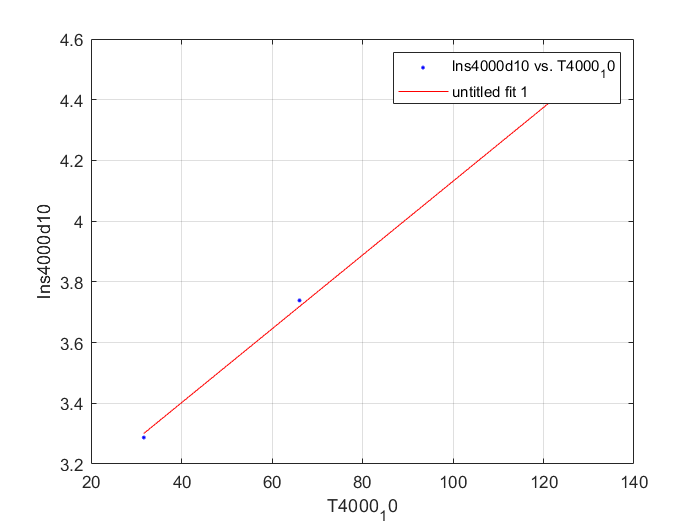

[xData, yData] = prepareCurveData( T4000_10, lns4000d10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4000d10 vs. T4000_10', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4000_10
ylabel lns4000d10
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01216  (0.007864, 0.01645)
  %     p2 =       2.916  (2.538, 3.293)

%Goodness of fit:
 % SSE: 0.0006152
  %R-square: 0.9992
 % Adjusted R-square: 0.9985
  %RMSE: 0.0248